## Testbed for Math Functions In C++

### Computing FFT

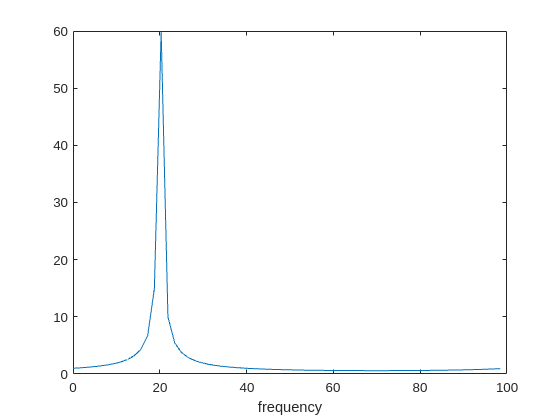

clear;
%generate a sample signal
    %specify N and sampling rate to generate a set of time values
    N = 64;
    Fs = 100;
    t = (0:1/Fs:(N/Fs - 1/Fs)).';

    %compute the complex signal
    F = 20; %Hz
    T = 1/F;
    f_t = exp(1j*2*pi* F * t);


%compute the fft
f = fft(f_t);

%plot the magnitude of the fft
freq_bins = (0:1/N:1-1/N) * Fs;
plot(freq_bins,abs(f))
xlabel("frequency");

%save the signal sample to a file
%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/sample_sinusoid.bin";
fileID = fopen(path,'w');
data = double(f_t);
data_to_export = reshape([real(data),imag(data)].',[],1);
fwrite(fileID,data_to_export, 'float32');
fclose(fileID);

%read the processed sample from the file
%to open a file from the GNU radio saved to a binary file
path = "/home/david/Documents/MATLAB_generated/computed_fft.bin";
fileID = fopen(path,'r');
read_data = fread(fileID,'float');

%convert to complex values
read_data = reshape(read_data,2,[]).';
read_data = read_data(:,1) + 1j * read_data(:,2);

%plot the magnitude of the processed fft to confirm it is correct
plot(freq_bins,abs(read_data))
xlabel("frequency");